# ETSMP Q2 eksamen – 2016-17

## Opgave 1: Stokastiske Variable

En diskret stokastisk variabel 𝑋 har følgende tæthedssfunktion (pmf)

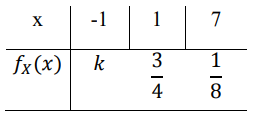

1) For hvilken værdi af *k* er $f_X \left(x\right)$ en gyldig tæthedsfunktion? Begrund svaret.

For at $f_X \left(x\right)$ er en gyldig tæthedsfunktion gælder at den total sandsynlighed er 1:

syms k
x = [-1 1 7];
fx = [k 3/4 1/8];

For en gyldig tæthedsfunktion $f_X \left(x\right)<1$ skal k være:

k = solve(sum(fx)== 1 , k)

$$k = \frac{1}{8}$$

2) Antag at $k=\frac{1}{8}$, find fordeling funktionen (cdf) $F_x \left(x\right)$ for $X$. Skitser $F_X \left(x\right)$.

clear syms

Fordelingsfunktionen cdf kan findes ved:

syms x
Fx(x) = piecewise( x < -1, 0, -1 <= x < 1, k, 1 <= x < 7, k+3/4, 7 <= x, k + 3/4 + 1/8)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<-1\\ \frac{1}{8} & \text{ if }x\in \left[-1,1\right)\\ \frac{7}{8} & \text{ if }x\in \left[1,7\right)\\ 1 & \text{ if }7\leq x \end{array}\right.$$

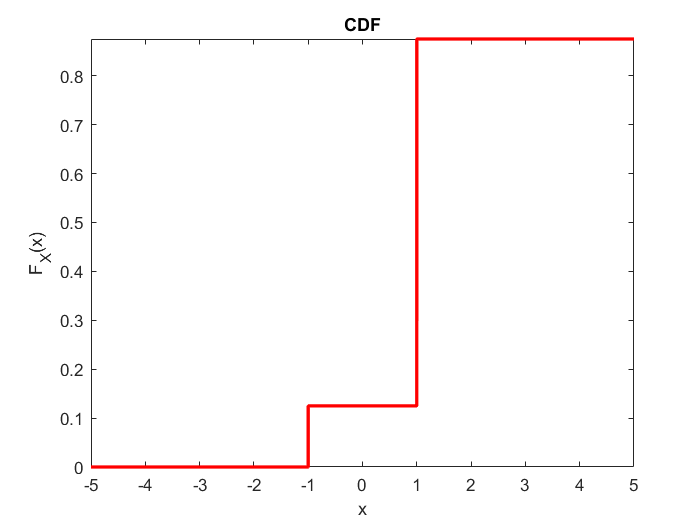

figure()  
fplot(Fx,'-r','LineWidth',2)
title('CDF');
xlabel('x');
ylabel('F_X(x)');

3) Brug $f_X \left(x\right)$ til at finde forventingsværdien E[X] og standard afvigelsen $\sigma_X$ for $X$. Antag at $k=\frac{1}{8}$.

Forventningsværdien findes ved:

fx = [1/8 3/4 1/8];
x = [-1 1 7];
EX = sum(x.*fx)

EX = 1.5000

Variansen findes ved:

EX2 = sum(x.^2.*fx)

EX2 = 7

Standardafvigelsen findes nu ved:

std = sqrt(EX2 - EX^2)

std = 2.1794

4) Hvis en funktion er defineret som $g\left(X=x\right)=3*x^2$. Find forventingsværdien $E\left\lbrack g\left(X=x\right)\right\rbrack$. Antag at $k=\frac{1}{8}$.

EgX = 3* EX2

EgX = 21

5) Angiv hvilke værdier X kan antage.

X kan antage -1, 1 og 7.

## Opgave 2: Stokastiske Processer

En kontinuer stokastisk process er givet ved:


$$X\left(t\right)=w\left(t\right)$$


Hvor $w\left(t\right)$ er i.i.d uniformt fordelt efter $w\left(t\right)~U\left(-2,-1\right)$.

1) Den stokastiske process $X\left(t\right)$ er samplet hvert sekundt, skitser 6 samples fra 0-5 s af en realisation. 

Angiv hvorledes realisationen er fremkommet, brug en tilfældigheds generator, f.eks. rand() i matlab. 

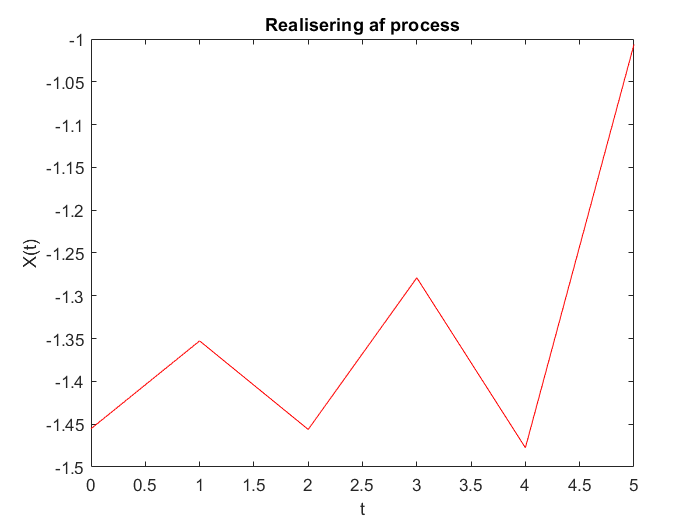

N = 6; % Antal samples

% A ~ U(-2,-1)
a = -2; b = -1;
% R = rand(M,N) returns an N-by-N matrix containing pseudorandom values drawn
% from the standard uniform distribution on the open interval(0,1).
w = a + (b-a).*rand(1,N);
t = [0:1:N-1];
figure()
plot(t, w,'-r')
title("Realisering af process"); xlabel("t"); ylabel("X(t)");

2) Bestem ensemble middelværdien og ensemble variansen for processen $E\left(t\right)$.

format rat

Ensemble middelværdien findes ved:

mean_X = (a+b)/2

mean_X =       -3/2     


Ensemble variansen findes ved:

variance_X = ((b-a)^2)/12

variance_X =        1/12    


3) Opskriv formlen til at bestemme den tidslige middelværdi for processen $X\left(t\right)$.

4) Angiv om processen $X\left(t\right)$ er WSS (stationær i den brede forstand) og om den er ergodisk. Begrund dine svar.

Da processen er uafhængig af tiden, middelværdien og variansen ændrer sig ikke, kan det konstanteres at processen 

er stationær i den brede forstand.

Processen er ergodisk, da ensemble tæthedsfunktionen kan findes ved en realisation når $t\to \infty$. 

## Opgave 3: Sandsynlighedsregning

format rat

En HIV test baseret på spyt er positiv i 92% af tilfældene, givet at man er HIV smittet. Den samme test er negativ i 98% af tilfældene, givet at man er ikke er HIV smittet. Af hele befolkningen er 0,1% smittet med HIV.

Hændelse A: HIV smittet

Hændelse B: Positiv test

`Prior: Sandsynlighed for at man er HIV smittet`

`Prior: Sandsynlighed for at man ikke er HIV smittet`

       

`Likelihood: Sandsynlighed for en positiv test givet at man er HIV smittet`

`Likelihood: Sandsynlighed for en positiv test givet at man ikke er HIV smittet`

`Likelihood: Sandsynlighed for en negativ test givet at man er HIV smittet`

`Likelihood: Sandsynlighed for en negativ test givet at man ikke er HIV smittet`

PrA = 0.001; % smittet
PrNA = 1-PrA; % ikke smittet
PrBA = 0.92; % positiv givet smittet
PrNBA = 1-PrBA; % negativ givet smittet
PrNBNA = 0.98; % negativ givet ikke smittet
PrBNA = 1-PrNBNA; % positiv givet ikke smittet

1) Hvad er sandsynligheden for at en person fra befolkningen både er HIV smittet og har en positiv test?

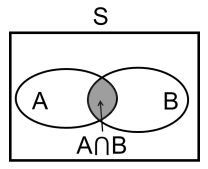

`Joint Events: Sandsynlighed for være HIV smittet og have en positiv test`

PrBAA = PrBA * PrA

2) Hvad er den totale sandsynlighed for at en person fra befolkningen har en positiv test?

`Total Probality: Sandsynligheden for at man har en positiv test (Sum Rule)`

PrB = PrBA * PrA + PrNA * PrBNA

3) Hvis en person fra befolkningen har en positiv test, hvad er sandsynligheden for, at han er HIV smittet? 

`Posterior: Sandsynligheden for at man er smittet givet en positiv test (Bayes Rule)`

PrAB = (PrBA * PrA) / PrB

4) Er begivenhederne ”At have en positv test” og ”være HIV smittet” uafhængige? begrund dit svar.

`Independence: To hændelser er uafhængige hvis følgende er gældende`

PrBAA
Pr_AB = PrA*PrB

De er derved ikke uafhængige.

## Opgave 4: Statistik